# Altitude Simulator

This program will take in a given set of input conditions that describe a rocket and predict its altitude.

For the experience, either view this sim with output on the right or view it with hidden code.

% Altitude Estimator
clear; clc; tic;

% Set up unit conversion factors
mToFt   = double(unitConversionFactor("m", "ft"));
lbfToN  = double(unitConversionFactor("lbf", "N"));
kgToLbm = double(unitConversionFactor("kg", "lbm"));
msToMph = double(unitConversionFactor("m/s", "mi/hr"));
mToMi   = double(unitConversionFactor("m", "mi"));

samples = 10; % Simulation dimension


% Set up optimization variables
thrust        = [100, 1300]*lbfToN; %   N    Rocket starting thrust
massFraction  = [0.4, 0.7]; %          -    Mass Fraction (Dry mass/total mass)
propMass      = [36, 48]/kgToLbm; %  kg   Propellant mass
isp           = [180, 200]; %          s    Specific impulse
diameter      = [4, 6]*2.54/100; % m    Rocket diameter    

names = ["thrust"; "massFraction"; "propMass"; "isp"; "diameter"];
ranges = [thrust; massFraction; propMass; isp; diameter];

arg = getOptimizationMatrix(names, ranges, samples);

fprintf('Analyzing %d cases...\n\n', numel(arg.thrust));

Analyzing 100000 cases...




% Set up criteria
% - The analysis will reject altitude values that do not meet these criteria
arg.minTWR = 0;

% Other input variables
arg.dragCoefficient = 0.6; %          -     Coefficient of drag
arg.startAltitude   = 2000/mToFt; %    m   Starting altitude (MSL)
arg.thrustDecay     = 10*lbfToN; %   N/s  Thrust lost per second
arg.ispDecay        = 0     ; %                        s/s  Specific impulse lost per second
arg.flightAngle     = 20; %          deg  Angle of flight
arg.railLength      = 40/mToFt; %    m   Launch rail length
arg.railButtonDist  = 4/mToFt; %    m    Rail button distance
arg.m_leftover      = 3/kgToLbm; %  kg   Propellant remaining in tanks
arg.dt = .1; % Timestep

 

results = getAltitude(arg);

Elapsed time is 1.926519 seconds.


Adjust the sliders below to explore the simulation. The charts show the values that are being used in the syms using a red line. The green line shows where the system performs optimally.

clf;

best = max(results.delta_h, [], "all");
best_index = results.delta_h==best;

% Insight plots:
opt.thrust = 6;
opt.massFraction = 4;
opt.propMass =10;
opt.isp =  4;
opt.diameter = 10;

fprintf('Best altitude: %.2f kft', best*mToFt/1000);

Best altitude: 134.35 kft

fprintf('Current altitude: %.2f kft', results.delta_h(opt.thrust, opt.massFraction,opt.propMass,opt.isp,opt.diameter)*mToFt/1000);

Current altitude: 36.21 kft


disp("All subsequent graphs are made with the assumption that other INPUT conditions are held constant, but not all OUTPUT conditions will be constant.");

All subsequent graphs are made with the assumption that other INPUT conditions are held constant, but not all OUTPUT conditions will be constant.


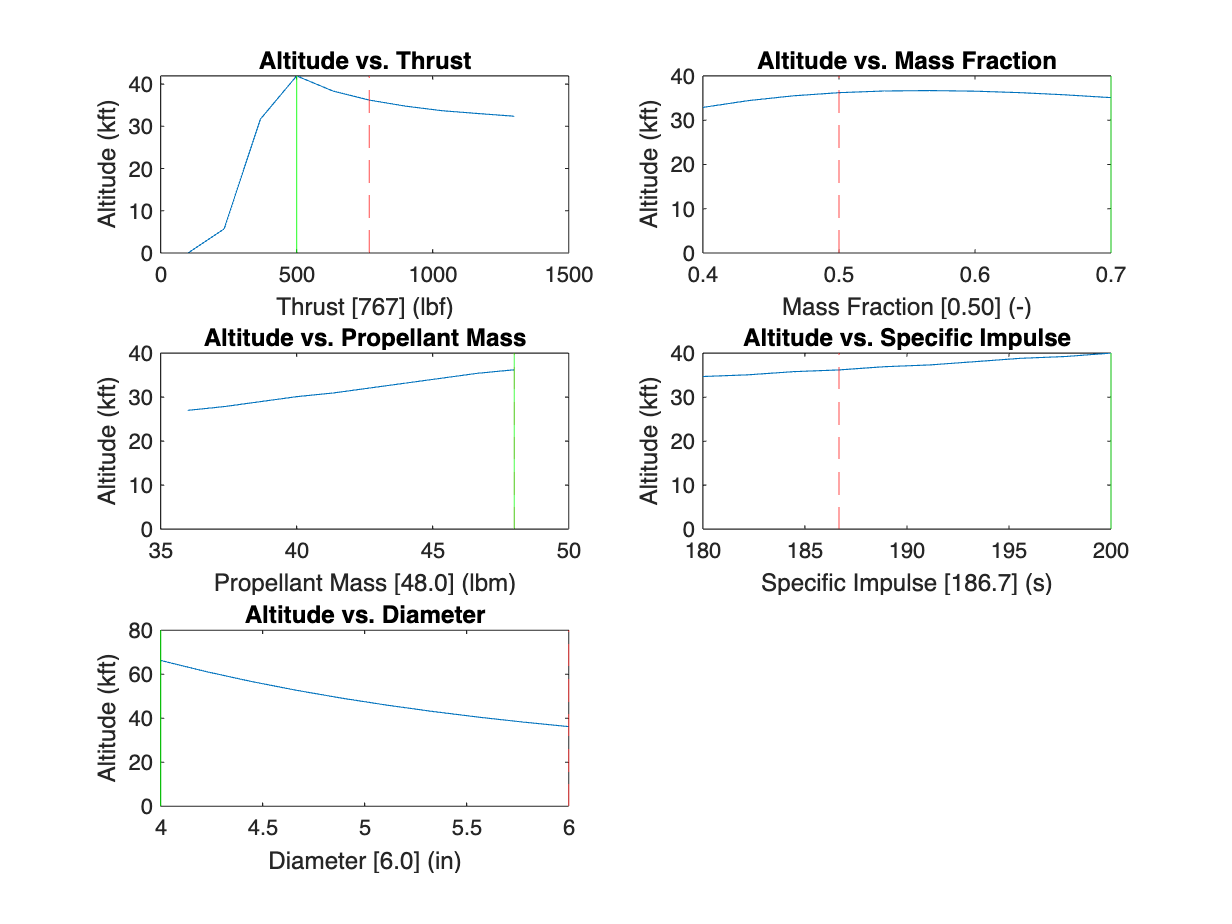


% Thrust
p.x =      arg.thrust(:, opt.massFraction,opt.propMass,opt.isp,opt.diameter)/lbfToN;
p.y = results.delta_h(:, opt.massFraction,opt.propMass,opt.isp,opt.diameter)*mToFt/1000;
p.l = arg.thrust(opt.thrust, opt.massFraction,opt.propMass,opt.isp,opt.diameter)/lbfToN;
subplot(3,2,1)
plot(p.x,p.y);
xline(p.l, 'r--');
xline(arg.thrust(best_index)/lbfToN,'g');
title('Altitude vs. Thrust');
xlabel(sprintf('Thrust [%.0f] (lbf)', p.l));
ylabel('Altitude (kft)');
yline(0);

% Mass Fraction
p.x = arg.massFraction(opt.thrust, :,opt.propMass,opt.isp,opt.diameter);
p.y =  results.delta_h(opt.thrust, :,opt.propMass,opt.isp,opt.diameter)*mToFt/1000;
p.l = arg.massFraction(opt.thrust, opt.massFraction,opt.propMass,opt.isp,opt.diameter);
subplot(3,2,2)
plot(p.x,p.y);
xline(p.l, 'r--');
xline(arg.massFraction(best_index),'g');
title('Altitude vs. Mass Fraction');
xlabel(sprintf('Mass Fraction [%.2f] (-)', p.l));
ylabel('Altitude (kft)');
yline(0);


% Propellant Mass
p.x =    arg.propMass(opt.thrust, opt.massFraction,:,opt.isp,opt.diameter)*kgToLbm;
p.y = results.delta_h(opt.thrust, opt.massFraction,:,opt.isp,opt.diameter)*mToFt/1000;
p.l = arg.propMass(opt.thrust, opt.massFraction,opt.propMass,opt.isp,opt.diameter)*kgToLbm;
subplot(3,2,3)
plot(squeeze(p.x),squeeze(p.y));
xline(p.l, 'r--');
xline(arg.propMass(best_index)*kgToLbm,'g');
title('Altitude vs. Propellant Mass');
xlabel(sprintf('Propellant Mass [%.1f] (lbm)', p.l));
ylabel('Altitude (kft)');
yline(0);


% Thrust Decay
p.x = arg.isp(opt.thrust,opt.massFraction,opt.propMass,:,opt.diameter);
p.y = results.delta_h(opt.thrust,opt.massFraction,opt.propMass,:,opt.diameter)*mToFt/1000;
p.l = arg.isp(opt.thrust,opt.massFraction,opt.propMass,opt.isp,opt.diameter);
subplot(3,2,4)
plot(squeeze(p.x),squeeze(p.y));
xline(p.l, 'r--');
xline(arg.isp(best_index),'g');
title('Altitude vs. Specific Impulse');
xlabel(sprintf('Specific Impulse [%.1f] (s)', p.l));
ylabel('Altitude (kft)');
yline(0);


% Diameter
p.x = arg.diameter(opt.thrust, opt.massFraction,opt.propMass,opt.isp,:)*100/2.54;
p.y =  results.delta_h(opt.thrust, opt.massFraction,opt.propMass,opt.isp,:)*mToFt/1000;
subplot(3,2,5)
p.l = arg.diameter(opt.thrust, opt.massFraction,opt.propMass,opt.isp,opt.diameter)*100/2.54;
plot(squeeze(p.x),squeeze(p.y));
xline(p.l, 'r--');
xline(arg.diameter(best_index)*100/2.54,'g');
title('Altitude vs. Diameter');
xlabel(sprintf('Diameter [%.1f] (in)', p.l));
ylabel('Altitude (kft)');
yline(0);

### Key Performance Data:

current = sub2ind(size(results.delta_h),opt.thrust, opt.massFraction,opt.propMass,opt.isp,opt.diameter);

fDisp('Apogee', ["km","kft"], results.delta_h(current)*[1/1000, mToFt/1000]);

Apogee               	11.04 km 	[36.21 kft]


fDisp('Inital TWR', "g", results.initialTWR(current));

Inital TWR           	7.983 g 


### Input Conditions:

fDisp('Initial thrust', ["kN", "lbf"], arg.thrust(current)*[1/1000, 1/lbfToN]);

Initial thrust       	3.41  kN 	[766.7 lbf]


fDisp('Mass Fraction', "", arg.massFraction(current));

Mass Fraction        	0.5    


fDisp('Dry mass', ["kg", "lbm"], results.m_dry(current)*[1, kgToLbm]);

Dry mass             	21.77 kg 	[48    lbm]


fDisp('Initial prop mass', ["kg", "lbm"], arg.propMass(current)*[1, kgToLbm]);

Initial prop mass    	21.77 kg 	[48    lbm]


fDisp('Total mass', ["kg", "lbm"], results.m_total(current)*[1, kgToLbm]);

Total mass           	43.54 kg 	[96    lbm]


fDisp('Drag coefficient', "", arg.dragCoefficient);

Drag coefficient     	0.6    


### Output Conditions:

fDisp('Max altitude (MSL)', ["km", "kft"], results.h_max(current)*[1/1000, mToFt/1000]);

Max altitude (MSL)   	11.65 km 	[38.21 kft]


fDisp('Maximum acceleration', "g", results.a_max(current)/9.81);

Maximum acceleration 	7.212 g 


fDisp('Maximum deceleration', "g", results.de_max(current)/9.81);

Maximum deceleration 	-9.132 g 


fDisp('Burn time', "s", results.t_burn(current));

Burn time            	11.9  s 


fDisp('Time to apogee', "s", results.t_apogee(current));

Time to apogee       	45.5  s 


fDisp('Maximum velocity', ["m/s", "mi/hr"], results.v_max(current)*[1, msToMph]);

Maximum velocity     	671.2 m/s 	[1501  mi/hr]


fDisp('Velocity off rail', ["m/s", "ft/s"], results.v_rail(current)*[1, mToFt]);

Velocity off rail    	34.59 m/s 	[113.5 ft/s]


fDisp('Maximum drag', ["kN", "lbf"], abs(results.D_max(current))*[1/1000, 1/lbfToN]);

Maximum drag         	1.844 kN 	[414.6 lbf]


fDisp('Downrange distance', ["km", "mi"], results.l(current)*[1/1000, mToMi]);

Downrange distance   	4.017 km 	[2.496 mi]
